# 1 DOF Cell Model in plane strain

## Data

clear all; close all; clc;
set_env;
addpath("Functions and Scripts\");
addpath("1DOF\");
load("cell_1dof_pstrain.mat")

% Data
eps1_max = 0.05;
% Symbolic variables ------------------------------------------------
% Geometry of the capacitor
syms x l_0 tf_0 dtf xi xi_0
syms epsilon_1(x) sigma_1(x) sigma_2(x) epsilon1_max

% syms epsilon_1(x) epsilon_2(x) epsilon_3(x) sigma_1(x)


## Equations

% Geometry ------------------------------
dt_f(x) = simplify(solve((x/2 - tf_0 / 2) / l_0 == (dtf / 2) / (l_0 - (xi - xi_0)), dtf), 25)

$$dt\_f(x) = -\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}$$

t_f(x) = tf_0 + dt_f;


w = pstrain_1dof.w

$$w = w_{0}$$

t_p = pstrain_1dof.t_p

$$t\_p = {\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)$$

l = pstrain_1dof.l

$$l = l_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)$$

A = pstrain_1dof.A

$$A = l_{0}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)$$

C_str = pstrain_1dof.C

$$C\_str(x) = \left\{ \begin{array}{cl} \frac{1}{\frac{{\mathrm{tf}}_{0}-\frac{\left({\mathrm{tf}}_{0}-x\right)\,\left(l_{0}-\xi +\xi_{0}\right)}{l_{0}}}{\epsilon_{f}\,l_{0}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}+\frac{2\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)}{\epsilon_{p}\,l_{0}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)}} & \text{ if }x\leq {\mathrm{tf}}_{0}+\frac{1}{10000000000}\\ \frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x}-\frac{\epsilon_{f}\,l_{0}\,w_{0}\,\log\left(\epsilon_{p}\,l_{0}\,\left({\mathrm{tf}}_{0}-x\right)-\epsilon_{p}\,l_{0}\,{\mathrm{tf}}_{0}-2\,\epsilon_{f}\,l_{0}\,{\mathrm{tp}}_{0}\,\left(\epsilon_{3}\left(x\right)+1\right)\right)\,\left(\epsilon_{1}\left(x\right)+1\right)}{{\mathrm{tf}}_{0}-x} & \text{ if }{\mathrm{tf}}_{0}+\frac{1}{10000000000}<x \end{array}\right.$$

Vol = pstrain_1dof.Vol

$$Vol = l_{0}\,{\mathrm{tp}}_{0}\,w_{0}\,\left(\epsilon_{1}\left(x\right)+1\right)\,\left(\epsilon_{3}\left(x\right)+1\right)$$

Vol_0 = pstrain_1dof.Vol_0

$$Vol\_0 = l_{0}\,{\mathrm{tp}}_{0}\,w_{0}$$


pstrain = sstrain1(pstrain_1dof, "PSTRAIN");
Vmax = pstrain.Vmax;
Uel = pstrain.Uel;
F = pstrain.F;
FVmax = pstrain.FVmax;
FVmin = pstrain.FVmin;
C = pstrain.C;
% Range limit
x_min = vpa(sdata1(pstrain.x_min), 4)

$$x\_min = 0.0001$$

x_max = subs(sstrain1(pstrain.x_max), epsilon1_max, eps1_max);
x_max = vpa(sdata1(rhs(isolate(x_max, x))), 4)

$$x\_max = 0.01611$$

x_minmax = [double(x_min) double(x_max)];


## Capacitance

% Min capacitance
Cmin = vpa(subs(sdata1(C), x, x_max), 4)

$$Cmin(x) = 1.864e-11$$


% Max C
Cmax = vpa(subs(sdata1(C), x, sdata1(tf_0)), 4)

$$Cmax(x) = 4.276e-10$$

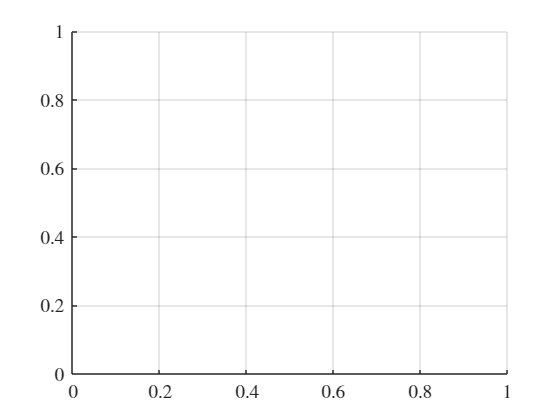

% Plot x - C(x)
myfig(1,"x - C(x)");
hold on

fplot(x, sdata1(C(x)), x_minmax, 'LineWidth', 2)

Error using fplot>singleFplot
Input must be a function or functions of a single variable.

Error in fplot>@(f1,f2)singleFplot(cax,{f1,f2},limits,extraOpts,args) (line 208)
        hObj = cellfun(@(f1,f2) singleFplot(cax,{f1,f2},limits,extraOpts,args),fn{1},fn{2},'UniformOutput',false);

Error in fplot>vectorizeFpl

xline(double(sdata1(x_max)), "--g", "x_{MAX}",'LabelOrientation','horizontal', 'FontWeight','bold')
hold off
title("x - C(x)")
xlabel("x [m]")
ylabel("C(x) [F]")


## Max voltage

% Max voltage
% Vmax(x) = A / C * min(epsilon_p * EBD_p, epsilon_f * EBD_f)

% Plot x - Vmax(x)
myfig(2,"x - Vmax(x)");
fplot(x, sdata1(Vmax(x),strpstrain), [double(x_min) double(x_max)], 'LineWidth', 2)
title("$x - V_{max}(x)$")
xlabel("x [m]")
ylabel("$V_{max}$(x) [V]")


## Force

% Force
Uel(x) = 2 * sdata1(1 / 2 * (sigma_1 * epsilon_1) * w * t_p * l, strpstrain)
F(x,V) = simplify(diff(Uel, x) - V^2 / 2 * diff(sdata1(C), x));

% Min and max force for V = 0 and V = Vmax
FVmin = vpa(F(x, 0), 4);
FVmax= vpa(F(x, sdata1(Vmax,strpstrain)), 4);

% Plot x - F(x) 
myfig(3,"x - F(x)"); hold on
fplot(x, FVmin, [double(sdata1(x_min)), double(sdata1(x_max))], 'LineWidth', 2, 'DisplayName', '$V_{min}$')
fplot(x, real(FVmax), [double(sdata1(x_min)), double(sdata1(x_max))], '--', 'LineWidth', 2, 'DisplayName', '$V_{max}$')
title("x - F(x)")
legend("Location","north")
xlabel("x [m]")
ylabel("F(x) [V]")


% Redefine x limits
x_range = double(x_min:1e-6:x_max);
[fvmax_peak, idx] = findpeaks(real(double(subs(FVmax, x_range))));
xstart = x_range(idx);
xend = double(min(sdata1(x_max), 0.01));


myfig(4,"x - F(x)")
hold on
fplot(x, FVmin, [xstart xend], 'LineWidth', 1.5, 'DisplayName', "$V_{MIN}$")
fplot(x, real(FVmax), [xstart xend], '--', 'LineWidth', 1.5, 'DisplayName', "$V_{MAX}$")
myxline(xstart, "--g", "x_{START}")
myxline(xend, "--g", "x_{MAX}")
hold off
legend("Location", "north")
title("x - F(x)")
xlim("padded")
xlabel("x [m]")
ylabel("F(x) [N]")

% Energy from x - F(x), use step of 2e-5
x_range = double(xstart:1e-5:xend);
FVmax_vec = double(subs(FVmax,x_range));
FVmin_vec = double(subs(FVmin,x_range));

Uel_Fx = double(trapz(x_range, FVmax_vec) - trapz(x_range, FVmin_vec))

## Q - V

% Plot Q - V
C_vec = double(subs(sdata1(C), x, x_range));
Vmax_vec = double(subs(sdata1(Vmax, strpstrain), x, x_range));
Q_vec = C_vec .* Vmax_vec;

V_vec = linspace(0, min(Vmax_vec), 100);
Qmaxstr = double(V_vec * Cmin);
Qminstr = double(V_vec * Cmax);

myfig(4,"Q - V"); clf
hold on
plot(Q_vec, Vmax_vec, 'DisplayName', "Voltage breakdown", "LineWidth", 1.5)
plot(Qminstr, V_vec, 'DisplayName', "Min. stretch", "LineWidth", 1.5)
plot(Qmaxstr, V_vec, 'DisplayName', "Max. stretch", "LineWidth", 1.5)
legend('Location','best')
xlabel("Q [A]")
ylabel("V [V]")
ylim([0, 1.1 * max(Vmax_vec)])
title("Q - V")
hold off



% Energy from Q - V
Uel_QV = trapz(Qmaxstr, V_vec) + max(Vmax_vec) * (Qminstr(end) - Qmaxstr(end)) - trapz(Qminstr, V_vec)

% Save results
res_1dof_pstrain.l = l;
res_1dof_pstrain.w = w;	
res_1dof_pstrain.t_p = t_p;
res_1dof_pstrain.A = A;
res_1dof_pstrain.t_f = t_f;
res_1dof_pstrain.C = C;	
res_1dof_pstrain.Vmax = Vmax;
res_1dof_pstrain.Uel = Uel;
res_1dof_pstrain.F = F;
res_1dof_pstrain.FVmin = FVmin;
res_1dof_pstrain.FVmax = real(FVmax);
res_1dof_pstrain.x_min = xstart;
res_1dof_pstrain.x_max = xend;
res_1dof_pstrain.x_range = x_range;
res_1dof_pstrain.Uel_Fx = Uel_Fx;
res_1dof_pstrain.Uel_QV = Uel_QV;
res_1dof_pstrain.Cmin = Cmin;
res_1dof_pstrain.Cmax = Cmax;
res_1dof_pstrain.Q_vec = Q_vec;
res_1dof_pstrain.V_vec = V_vec;
res_1dof_pstrain.Vmax_vec = Vmax_vec;
res_1dof_pstrain.Qmaxstr = Qmaxstr;
res_1dof_pstrain.Qminstr = Qminstr;

save("1DOF\res_1dof_pstrain.mat", "res_1dof_pstrain")



